# **Load Flow Analysis with Newton Raphson Method**

Created by Akanit KWANGKAEW

clc
clear all;

MVAb=100;
KVb=12.66;
Zb=(KVb^2)/MVAb;

% Load_set = load( '33BusTest-load.txt');
% n_bus = size(Load_set,1)
% Gen_set = load( '33BusTest-gen.txt');
% Line_set = load( '33BusTest-line.txt');


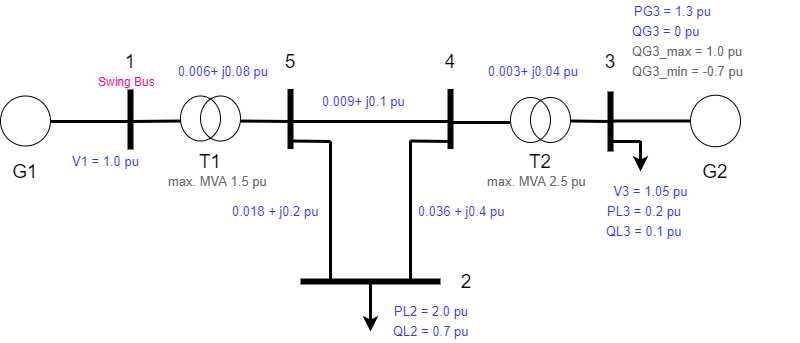

Load_set = importdata( '5BusSample-load.txt');
Gen_set = importdata( '5BusSample-gen.txt');
n_bus = size(Load_set,1)

n_bus = 5


Line_set = load( '5BusSample-line.txt');


### Step 1: Create ***Y Bus*** (***Admittance*** ***Matrix***)

[Y_bus, Theta] = Get_Ybus( Line_set );

Y_bus_abs = abs(Y_bus) %Magnitude Value

Y_bus_abs =    12.4650         0         0         0   12.4650
         0    7.4698         0    2.4899    4.9799
         0         0   24.9300   24.9300         0
         0    2.4899   24.9300   37.3787    9.9597
   12.4650    4.9799         0    9.9597   27.4039


#### Defining the Ybus elements (Admittance Matrix)

Y_bus

Y_bus =    0.9323 -12.4301i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.9323 +12.4301i
   0.0000 + 0.0000i   0.6696 - 7.4397i   0.0000 + 0.0000i  -0.2232 + 2.4799i  -0.4464 + 4.9598i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.8645 -24.8602i  -1.8645 +24.8602i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.2232 + 2.4799i  -1.8645 +24.8602i   2.9805 -37.2597i  -0.8928 + 9.9197i
  -0.9323 +12.4301i  -0.4464 + 4.9598i   0.0000 + 0.0000i  -0.8928 + 9.9197i   2.2714 -27.3096i


#### Theta matrix


Theta_deg = 180*Theta / pi ; %Angle (Degree) 
Theta

Theta =    -1.4959         0         0         0    1.6457
         0   -1.4810         0    1.6606    1.6606
         0         0   -1.4959    1.6457         0
         0    1.6606    1.6457   -1.4910    1.6606
    1.6457    1.6606         0    1.6606   -1.4878


#### Defining the know states

v1 = 1.0;
d1 = 0;
v3 = 1.05;
d3 = 0;





#### Defining the power injections

%load
p2 = -2.0;
q2 = -0.7;

%generation and load
p3 = 1.3-0.2;
q3 = -0.1;






#### Defining the initial values of unknown

v2 = complex(1,0) ;
d2 = 0;
v4 = complex(1,0) ;
d4 = 0;
v5 = complex(1,0) ;
d5 = 0;

Pspec = [NaN p2 p3 NaN NaN ];
Qspec= [NaN q2 q3 NaN NaN ];
Vspec = [v1 NaN v3 NaN NaN];
Dspec = [d1 NaN d3 NaN NaN];




P = [0 p2 p3 0 0 ];
Q = [0 q2 q3 0 0 ];
V =  [v1 1 v3 1 1];
D = [d1 0 d3 0 0];



disp('------------------------------------------------')

------------------------------------------------


### Step 2: Define size of **PV**

For the bus that given **P** and **Q :** Defind **PQ-bus / Bus-Load** type of calculation 

For the bus that  given **P** and** V :** Defind **PV-bus / Bus-Volatage-Control** type of calculation (No need to find V for that bus)

`Note the final result is to determine the voltage(``V``) and theta`$\left(\delta \right)$

Bus1 : Slack Bus

Bus2 : PQ-Bus (LOAD-BUS)

Bus3 : PV-Bus

Bus4 : PQ-BUS (LOAD-BUS)

Bus5 : PQ-BUS (LOAD-BUS)

Therefore, we can formulate $\Delta P\;\textrm{and}\;\Delta Q$ in Carterian coordinate as :

$\left\lbrack \begin{array}{c}
\Delta p_2 \\
\Delta p_3 \\
\Delta p_4 \\
\Delta p_5 \\
\Delta q_2 \\
\Delta q_3 \\
\Delta q_4 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{cccccc}
\frac{\partial p_2 }{\partial \delta_2 } & \ldotp \ldotp \ldotp  & \frac{\partial p_2 }{\partial \delta_5 } & \frac{\partial p_2 }{\partial v_2 } & \ldotp \ldotp \ldotp  & \frac{\partial p_2 }{\partial v_5 }\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp \\
\ldotp \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp \\
\frac{\partial p_5 }{\partial \delta_2 } & \ldotp \ldotp  & \frac{\partial p_5 }{\partial \delta_5 } & \frac{\partial p_5 }{\partial v_2 } & \ldotp \ldotp  & \frac{\partial p_5 }{\partial v_5 }\\
\frac{\partial q_2 }{\partial \delta_2 } & \ldotp \ldotp \ldotp  & \frac{\partial q_2 }{\partial \delta_5 } & \frac{\partial q_2 }{\partial v_2 } & \ldotp \ldotp \ldotp  & \frac{\partial q_2 }{\partial v_5 }\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
\frac{\partial q_4 }{\partial \delta_2 } & \ldotp \ldotp \ldotp  & \frac{\partial q_4 }{\partial \delta_5 } & \frac{\partial q_4 }{\partial v_2 } & \ldotp \ldotp \ldotp  & \frac{\partial q_4 }{\partial v_5 }
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
\Delta \delta_2 \\
\Delta \delta_3 \\
\Delta \delta_4 \\
\Delta \delta_5 \\
\Delta V_2 \\
\Delta V_4 \\
\Delta V_5 
\end{array}\right\rbrack$

or,


$$\left\lbrack \begin{array}{c}
\Delta p_2 \\
\Delta p_3 \\
\Delta p_4 \\
\Delta p_5 \\
\Delta q_2 \\
\Delta q_4 \\
\Delta 5
\end{array}\right\rbrack =$$

$$\left\lbrack \begin{array}{cccccc}
 &  &  &  &  & \\
\; & J_1  & \; & \; & J_2  & \;\\
\; & \; & \; & \; & \; & \;\\
\; & \; & \; & \; & \; & \;\\
\; & J_3  & \; & \; & J_4  & \;\\
\; & \; & \; & \; & \; & \;\\
\; & \; & \; & \; & \; & \;
\end{array}\right\rbrack$$

$$\left\lbrack \begin{array}{c}
\Delta \delta_2 \\
\Delta \delta_3 \\
\Delta \delta_4 \\
\Delta \delta_5 \\
\Delta V_2 \\
\Delta V_4 \\
\Delta V_5 
\end{array}\right\rbrack \;$$

$$------------------\;\left(1\right)$$


### Step 3: Initialize voltage to all buses except the slack busbar.

%Calculate in Per Unit (pu)
v1  %Slack Bus

v1 = 1

d1 

d1 = 0


%  pol2cart(theta (radian),rho)
disp('V3 is given (no need to calculate.).')

V3 is given (no need to calculate.).


v3 

v3 = 1.0500

d3

d3 = 0

fprintf('Theta(V3) : %.2f',angle(v3));

Theta(V3) : 0.00

fprintf('Magnitude(V3) : %.2f',abs(v3));

Magnitude(V3) : 1.05

v = [v1 v2 v3 v4 v5]

v =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0500 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


d = [d1 d2 d3 d4 d5]

d =      0     0     0     0     0


### Step 4: Defind Iterations and $\varepsilon =0\ldotp 1%$ (convergence tolerance)

tolerance = 0.001;

### **Step 5: Power Calculation **

- In case **PQ-bus / Bus-Load** Type (know P, Q) - > determine **P** and **Q** (The given P,Q are the spec number, not calculation)

- In case **PV-bus / Bus-Voltage-Control** Type (know P, V)- > determine only **P ** (The given P is the spec number, not calculation)

Let, 

$\left\lbrack \begin{array}{c}
\Delta \mathit{\mathbf{P}}\\
\Delta \mathit{\mathbf{Q}}
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{cc}
J_1  & J_2 \\
J_3  & J_4 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\Delta E\\
\Delta F
\end{array}\right\rbrack$ ------------------ (2)

The network has $n$ nodes, where $k^{\textrm{th}} =2,\ldotp \ldotp \ldotp ,n:$ 


$$I_k =\sum_{j=1}^n Y_{\textrm{kj}} V_j$$



$$S_k^* =V_k^* I_k$$



$$P_k =V_k \sum_{i=1}^n Y_{\textrm{kn}} V_n \textrm{Cos}\left(\delta_k -\delta_n -\theta_{\textrm{kn}} \right)$$



$$Q_k =V_k \sum_{i=1}^n Y_{\textrm{kn}} V_n \textrm{Sin}\left(\delta_k -\delta_n -\theta_{\textrm{kn}} \right)$$


**Round 0**

n_bus = size(v,2);

iter = 1;
p_dmm = 0;
q_dmm = 0;
for round = 1:iter
    for k = 2:n_bus
        
        for i = 1:n_bus

         p_dmm = p_dmm + calPower( Y_bus_abs(k,i), v(k), v(i), d(i), d(k), Theta(k,i) );  
         q_dmm = q_dmm + calReactivePower( Y_bus_abs(k,i), v(k), v(i), d(i), d(k), Theta(k,i) );  
         
        end
        Pcal(k) = p_dmm;
        Qcal(k) = p_dmm;
%         disp('-----------')
    end
end

Pcal

Pcal =          0   -0.0000    0.0979    0.0047    0.0047


Qcal

Qcal =          0   -0.0000    0.0979    0.0047    0.0047


### **Step 6: Error Calculation **

Diff_P = P- Pcal

Diff_P =          0   -2.0000    1.0021   -0.0047   -0.0047


Diff_Q = Q - Qcal

Diff_Q =          0   -0.7000   -0.1979   -0.0047   -0.0047


Diff = max( max( P - Pcal, Q - Qcal))

Diff = 1.0021

### Step 7: Tolerance Checking

tolerance

tolerance = 1.0000e-03

if ( Diff > tolerance) 
    disp('Continue using Jacobian')
end

Continue using Jacobian


### Step 8: Determine Jacobian Matrix

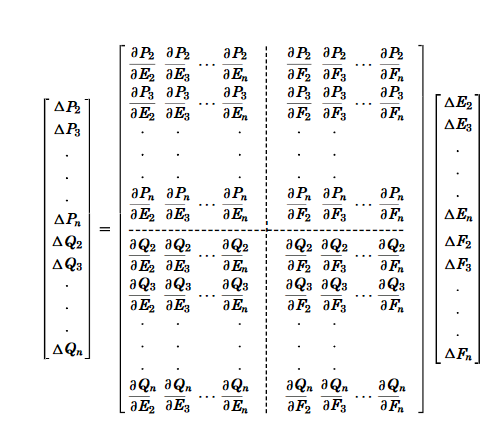




PV_index = [0 1 1 1 1];
PQ_index = [0 1 0 1 1];
V_index = [0 1 0 1 1];

% J = calJacobian( P_unknown_index , Q_unknown_index, V_unknown_index, Yin, Tin, Pin, Qin, Din, Vin)

J = calJacobian( PV_index, PQ_index, V_index , Y_bus_abs, Theta, Pcal, Qcal, D, abs(V) )

p_size = 5

$$J1 = \left(\begin{array}{cccc} 7.4397 & 0 & -2.4799 & -4.9598\\ 0 & 26.1032 & -26.1032 & 0\\ -2.4799 & -26.1032 & 38.5027 & -9.9197\\ -4.9598 & 0 & -9.9197 & 27.3096 \end{array}\right)$$

$$J2 = \left(\begin{array}{ccc} 0.6696 & -0.2232 & -0.4464\\ 0 & -1.9577 & 0\\ -0.2232 & 2.8872 & -0.8928\\ -0.4464 & -0.8928 & 2.2714 \end{array}\right)$$

$$J3 = \left(\begin{array}{cccc} -0.6696 & 0 & 0.2232 & 0.4464\\ 0.2232 & 1.9577 & -3.0737 & 0.8928\\ 0.4464 & 0 & 0.8928 & -2.2714 \end{array}\right)$$

$$J4 = \left(\begin{array}{ccc} 7.4397 & -2.4799 & -4.9598\\ -2.4799 & 36.0167 & -9.9197\\ -4.9598 & -9.9197 & 27.3096 \end{array}\right)$$

$$J = \left(\begin{array}{ccccccc} 7.4397 & 0 & -2.4799 & -4.9598 & 0.6696 & -0.2232 & -0.4464\\ 0 & 26.1032 & -26.1032 & 0 & 0 & -1.9577 & 0\\ -2.4799 & -26.1032 & 38.5027 & -9.9197 & -0.2232 & 2.8872 & -0.8928\\ -4.9598 & 0 & -9.9197 & 27.3096 & -0.4464 & -0.8928 & 2.2714\\ -0.6696 & 0 & 0.2232 & 0.4464 & 7.4397 & -2.4799 & -4.9598\\ 0.2232 & 1.9577 & -3.0737 & 0.8928 & -2.4799 & 36.0167 & -9.9197\\ 0.4464 & 0 & 0.8928 & -2.2714 & -4.9598 & -9.9197 & 27.3096 \end{array}\right)$$

### Step 9: Determine Voltage and Angle


$$\left\lbrack \begin{array}{c}
\Delta \delta \\
\Delta V
\end{array}\right\rbrack ={\left\lbrack J\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
\Delta P\\
\Delta Q
\end{array}\right\rbrack$$


Diff_P_marked = markOff_1D(PV_index, Diff_P )';
Diff_Q_marked  = markOff_1D(PQ_index, Diff_Q )';

D_marked= markOff_1D(PV_index, D )';
V_marked = markOff_1D(V_index, V )';
[D_marked ; V_marked]

ans =      0
     0
     0
     0
     1
     1
     1


Inv_J_PQ = J \ [Diff_P_marked ; Diff_Q_marked]

$$Inv\_J\_PQ = \left(\begin{array}{c} -0.3281\\ -0.0149\\ -0.0518\\ -0.0788\\ -0.1456\\ -0.0189\\ -0.0330 \end{array}\right)$$

% Update V and D
% D_new 
% V_new 
% Ans of New [ D_new ; V_new ]
Inv_J_PQ + [D_marked ; V_marked]

$$ans = \left(\begin{array}{c} -0.3281\\ -0.0149\\ -0.0518\\ -0.0788\\ 0.8544\\ 0.9811\\ 0.9670 \end{array}\right)$$